# **Práctica 4: Convolución y Correlación de señales en tiempo continuo**

**Integrantes:**

Contreras Avilés Citlali Anahí

Gallegos Ruiz Diana Abigail

Morgado Reséndiz Lisardo René

Ramírez Aniceto Lauro Alexis

Rojas Gómez Ian

**PROFESOR:** Rafael Martínez Martínez

**GRUPO:** 2TV1

## **Introducción**

### **Métodos básicos de integración numérica**

El número asociado a $\int_a^b f(x)  dx$ nos define el área bajo la curva formada por $f\left(x\right)$. Recordemos el teorema fundamental del cálculo.

Si $f$ es integrable y      $
\frac{dF(x)} {dx} = f(x) \\$  Entonces:

                        
$$\int_a^b f(x) dx = F(b)-F(a)$$


Cuando encontrar F se vuelve muy complejo o imposible se utilzan distintas técnica de integración como las que se presentan a continuación. La integración numérica  consiste en sustituir funciones por polinomios lo suficientemente parecidos, tal que integrar los polinomios será casi equivalente a integrar a la función.

### Fórmulas cerrradas de Newton- Cotes  

Para este método se necesita que la función $f\left(x\right)$ es derivable un número determinado de veces y la derivada en contínua. De acuerdo a la teoría de Lagrange  

                                        
$$ f(x) = P(x)+ \frac{f^{n+1}(\xi(x))} {(n+1)!} (x-x_0)(x-x_1) \ ... \ (x-x_n)$$


Las fórmulas de Newton-Cotes dependerán del grado del polinomio $P\left(x\right)$, están fórmulas reciben el nombre de  Fórmula cerrada de $(n+1) \ puntos$ donde $n$ es el grado del polinomio.  Se destacan los siguientes puntos :

                                            
$$x_0=a  \ \ \ \ \ \ \ \ \ \ \ \  h=\frac {b-a}{n}     \\
 x_n=b \ \ \ \ \ \ \ \ \ \ \ \   x_i = x_0+ih\ ; \ i = 0,1, \ ... \ n$$


Donde :

$x_0 \;$es el primer punto

$x_n$ último punto

$h$ , también llamado **paso** , es la distancia  que hay entre punto y punto. 

$x_i \;$son los puntos intermedios de la interpolación

#### `Regla del trapecio`

Se utiliza un polinomio de grado 1 , por lo que solo se necesitan dos puntos de interpolación. Se define como

                      
$$\int_{x_0}^{x_1}f(x) dx = \frac {h}{2} [f(x_0)+f(x_1)]-\frac{h^3}{12}f^{´´}(\xi)   \ \ \ \ \ x_0 < \xi <x_1$$


Donde:      $\begin{array}{l}
x_0 =a\;\;\;\;\;\;\;\;\;h=b-a\;\;\;\;\;\;\;\\
x_1 =b\;\;\;\;\;\;\;\;\;x_1 =a+i\left(b-a\right)\;\;\;\;;\;\;i=0,1
\end{array}$

                                                    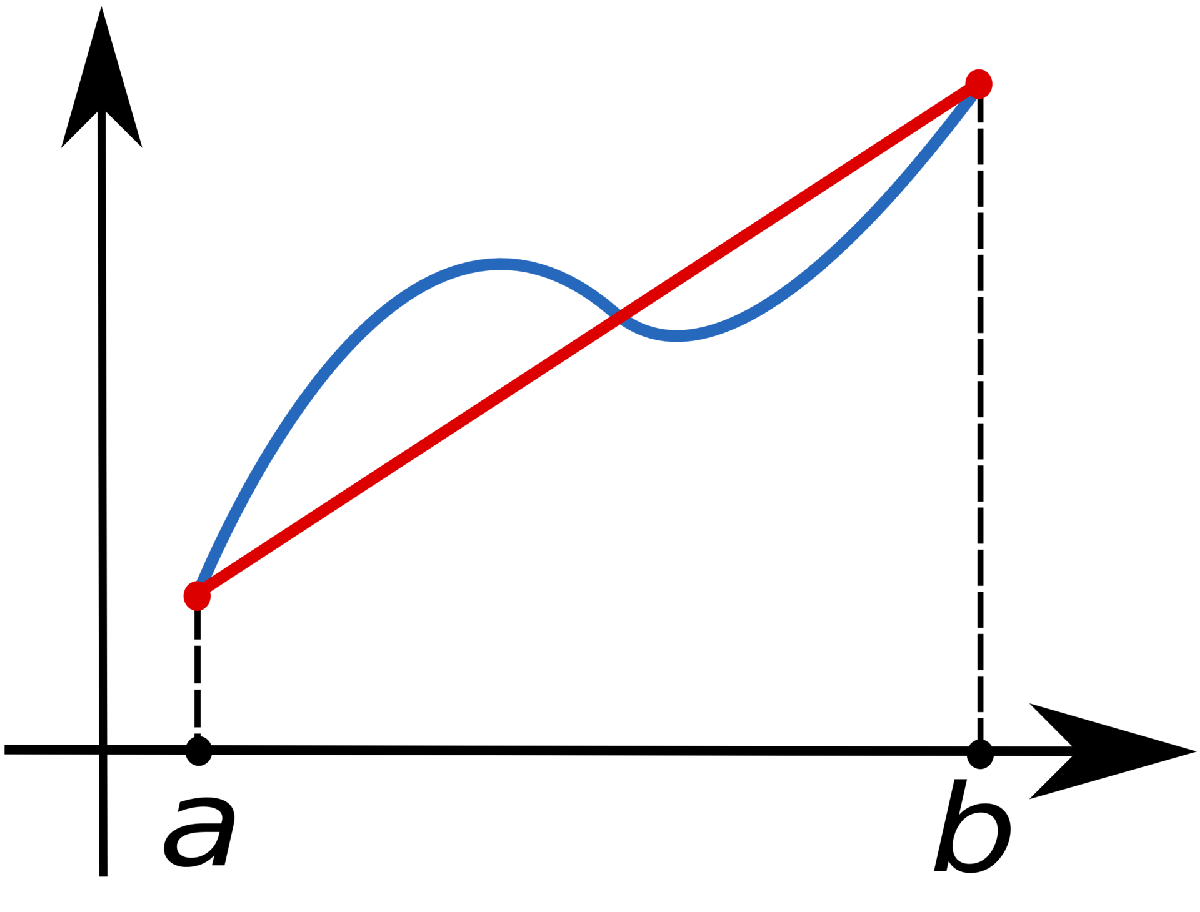

* Ejemplo:*


$$\int_{-1} ^1e^{-x^2}dx= \frac{2}{2} [e^-1+e^-1]-\frac{8}{12}[-2e^{-\xi^2} (1-2\xi^2)]  \ \ \ \ \ \ -1<\xi <1 \\
\int_{-1} ^1e^{-x^2}dx= 0.7357 + \frac {4}{3}e^{-\xi^2} (1-2\xi^2)  \ \ \ \ \ \ -1<\xi <1 $$


#### `Regla de Simpson` 

Se utiliza un polinomio de grado 2 , por lo que solo se necesitan tres puntos de interpolación. Se define como:


$$\int_{x_0}^{x_2}f(x) dx = \frac {h}{2} [f(x_0)+4f(x_1)+f(x_2)]-\frac{h^5}{90}f^{(4)}(\xi)   \ \ \ \ \ x_0 < \xi<x_2$$


Donde:      $\begin{array}{l}
x_0 =a\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;h=\frac{b-a}{2}\;\;\;\;\;\;\\
x_1 =\frac{b-a}{2}\;\;\;\;\\
x_2 =b\;\;\;\;\;\;\;\;\;
\end{array}$

                                                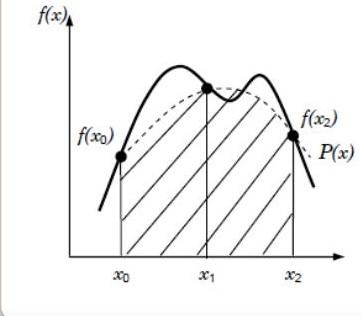

*Ejemplo:*


$$\int_{-1} ^1e^{-x^2}dx= \frac{1}{3} [e^{-1}+4e^0+e^{-1}]-\frac{1}{90}[-4e^{-\xi^2} 
 (-4\xi^4 + 12\xi^2 -3)]  \ \ \ \ \ \ -1<\xi <1 \\
\int_{-1} ^1e^{-x^2}dx= 1.5785 + \frac {2}{45}e^{-\xi^2} (-4\xi^4+12\xi^2-3)  \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ -1<\xi <1 $$


#### `Regla 3/8 de Simpson`

Se utiliza un polinomio de grado 2 , por lo que solo se necesitan cuatro puntos de interpolación. Se define como:


$$\int_{x_0}^{x_3}f(x) dx = \frac {3}{8}h [f(x_0)+3f(x_1)+3f(x_2)+f(x_3)]-\frac{3h^5}{80}f^{(4)}(\xi)   \ \ \ \ \ x_0 < \xi <x_3$$


Donde:      $\begin{array}{l}
x_0 =a\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;h=\frac{b-a}{3}\;\;\;\;\\
x_1 =\frac{2a+b}{3}\;\;\;\\
x_2 =\frac{2b+a}{3}\;\;\;\;\;\;\\
x_3 =b\;\;\;\;\;\;\;\;\;
\end{array}$

                                    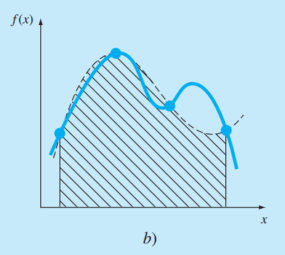

*Ejemplo:*


$$\int_{-1} ^1e^{-x^2}dx= \frac{3}{8}(\frac{2}{3}) [e^{-1}+3e^{-\frac {1}{9}}+ 3e^{-\frac {1}{9}} + e^{-1} ]-\frac{3}{80} (\frac {2}{3})^5 \  [-4e^{-\xi^2} 
 (-4\xi^4 + 12\xi^2 -3)]  \ \ \ \ \ \ -1<\xi <1 \\
\int_{-1} ^1e^{-x^2}dx= 1.5261 + \frac {8}{405}e^{-\xi^2} (-4\xi^4+12\xi^2-3)  \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ -1<\xi <1 $$


### Fórmulas cerradas de Newton-Cotes 

Cuando subdividimos la función en varios intervalos podemos utilizar las fórmulas cerradas de Newton-Cotes 

#### `Regla compuesta del trapecio`


$$\int_a^bf(x)dx = \frac{h}{2}\left[f(a)+2\displaystyle\sum_{j=1}^{n-1} f(x_j)+f(b)\right] - \frac{b-a}{12}h^2f^{´´}(\mu) \ \ \ \ \ \mu \  \epsilon \  (a,b)$$


                                        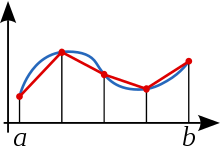

Donde $\begin{array}{l}
n\;\;\textrm{es}\;\textrm{el}\;\textrm{número}\;\textrm{de}\;\textrm{subintervalos}\;\\
h=\frac{b-a}{n}\;\;\left(\textrm{paso}\right)\\
x_j =a+j\;h\;\;\;\;;\;\;\;j=0,1,2,\;\ldotp \ldotp \ldotp \;,n\;\;\;\;\;\;
\end{array}$

*Ejemplo:*

Si  n=10  entonces       $
h=\frac{1-(-1)}{10}=0.2 \\
$   y $x_0 =-1\;;x_1 =-0\ldotp 8\;,x_2 =-0\ldotp 6,\;\;\ldotp \ldotp \ldotp \;\;,x_9 =0\ldotp 8\;,\;x_{10} =1$


$$\int_{-1}^1e^{-x^2}dx =\frac{0.2}{2}\left[e^{-1}+2\displaystyle\sum_{j=1}^{n-1}e^{-x_j^2}+e^{-1}\right] -frac{2}{12}(0.2)^3 \left[-2e^{-\mu^2}(1-2\mu^2)\right] \\
\int_{-1}^1e^{-x^2}dx =1.4887 + 0.0133 e^{-\mu^2}(1-2\mu^2) \ ; \ -1<\mu<1
$$


#### `Regla compuesta de Simpson`


$$\int_a^bf(x)dx = \frac{h}{3}\left[f(a)+2\displaystyle\sum_{j=1}^{\frac{n}{2}-1} f(x_{2j})+ 4  \displaystyle\sum_{j=1}^{\frac{n}{2}}f(x_{2j-1})+f(b) \right] \ \ ;   \ \ \ \ \ \mu \  \epsilon \  (a,b)$$


                                            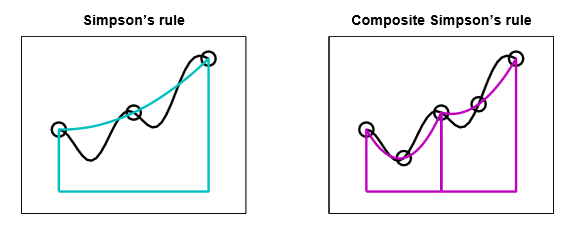

Donde :     $\begin{array}{l}
n\;\textrm{par}\;\textrm{número}\;\textrm{de}\;\textrm{subintervalos}\;\\
h=\frac{b-a}{n}\;\;\;\;\;\;\left(\textrm{paso}\right)\\
x_j =a+j\;h\;;\;\;\;\;j=0,1,\;\ldotp \ldotp \ldotp \;,\;n
\end{array}$

*Ejemplo:*

Si  n=10  entonces       $
h=\frac{1-(-1)}{10}=0.2 \\
$     y     $x_0 =-1\;;x_1 =-0\ldotp 8\;,x_2 =-0\ldotp 6,\;\;\ldotp \ldotp \ldotp \;\;,x_9 =0\ldotp 8\;,\;x_{10} =1$


$$\int_{-1}^1e^{-x^2}dx =\  \frac{0.2}{3} \ \left[e^{-1}+2\displaystyle\sum_{j=1}^{4} e^{-x_{2j}^2} + 4  \displaystyle\sum_{j=1}^{5}e^{-x_{2j-1}^2}+ e ^{-1} \right]   
-\frac {2}{180} (0.2)^4 \left[ -4e^{\mu^2}(-4\mu^4 + 12 \mu^2 -3) \right ]
$$


`Cuadratura Gausianna` 

Definamos algunos conceptos importantes: 

- El grado de precisión es el polinomio de mayor grado de tal manera que las fórmulas de Newton-Cotes son exactas (El error es 0).

- La cuadratura es una técnica que consiste en aproximar integrales por evaluaciones de las funciones en determinados puntos por determinadas  constantes. 

La cuadratura Gaussiana se define como:

                                        $\int_{-1}^{1}P(x)dx = \displaystyle\sum_{i=1}^nC_1 P(x_i)$     $P\left(x\right)$con grado menor que $2n$.

Donde:

$P_n \left(x\right)$ polinomio de Legendre de grado $n$.

$x_1 ,x_{2,\;} \;\;\ldotp \ldotp \ldotp \;\;,x_n \;$ son raíces de $P_n \left(x\right)$

$C_i$ son los coeficientes  tales que :  $C_i=\int_{-1}^1 \ \displaystyle\prod_{j=1}^n \frac{x-x_j}{x_i-x_j} dx$   

Las raíces y los coeficientes también se pueden obtener mediante la siguiente tabla:

                                                    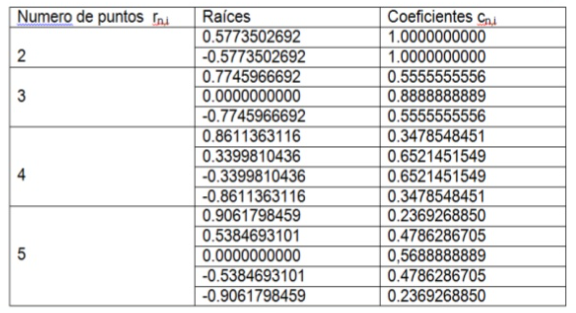

Si se desea integrar en un intervalo distinto a [-1,1] se debe hacer el siguiente ajuste:


$$\int_a^bf(x)dx = \int_{-1}{1}f\left(\frac{(b-a)t +b+a}{2}\right) \frac{b-a}{2} dt$$


*Ejemplo:*

*Para *$n=2$


$$\int_{-1}^{1}e^{-x^2}dx  \approx e^{-(0.5773502692)^2}+ e^{-(0.5773502692)^2} \\
\int_{-1}^{1}e^{-x^2}dx  \approx  1.4331$$


Para $n=3$


$$\int_{-1}^{1}e^{-x^2}dx  \approx
0.555555\  e^{-(0.774596692)^2}+ 0.8888888889 +0.55555555 \ e^{-(0.774596692)^2} \\
\int_{-1}^{1}e^{-x^2}dx  \approx  1.4986$$


## **Convolución: PR04**

### **Problema 1**

clear all; clc; close all;

Las Señales del PR04, 1 problema son:

$\[ x(t) = \begin{cases} 
      -t + 1 & 0\leq t \lt 1 \\
      t-1 & 1\lt x\leq 2 \\
      0 & otro \ caso 
   \end{cases}
\]$  y $\[f(t) = \begin{cases}
 1 & 0 \leq t \leq 1 \\
 0 & otro \ caso
 \end{cases}
\]$ 

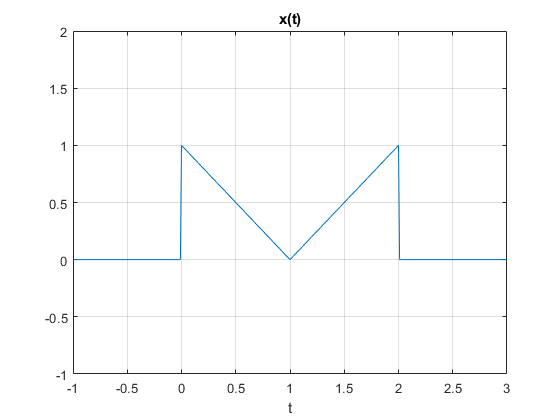

x = @(t) (-t+1).*((t >= 0) & (t<1)) + (t-1).*((1 < t)&(t <= 2));
xV = (-1: 0.01: 4);
plot(xV, x(xV));
axis([-1 3 -1 2]);
title('x(t)');
xlabel('t');
grid on;

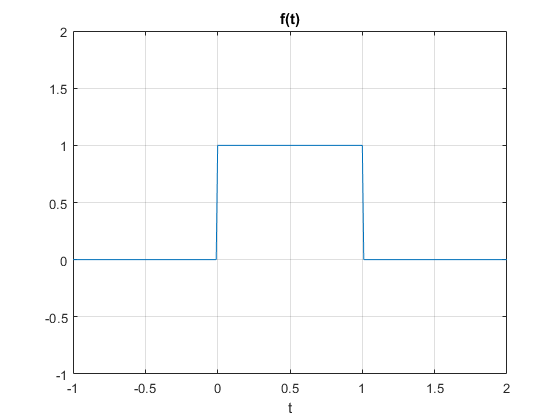

f = @(t) (1.*((0 <= t)&(t <= 1)));
fV = (-1: 0.01: 2);

plot(fV, f(fV));
axis([-1 2 -1 2]);
title('f(t)');
xlabel('t');
grid on;

Para aplicar la convolución, usaríamos la definición y nuestra señal inversa movible  va a ser f(t):

$h(x) = x(t)*f(t)= \int_{-\infty}^{\infty}x(\tau)f(t-\tau)\, d\tau$}

La convolucíon resultante sería:


$$\[ h(t) = 
\begin{cases}
-\frac{t^2}{2}+ t & 0 \lt t \leq 1 \\
t^2-3t+\frac{5}{2} &1 \lt t \leq2 \\ 
-\frac{t^2}{2}+ 2t - \frac{3}{2} & 2 \lt t \le 3 \\
0 & otro\ caso
\end{cases}
\]$$


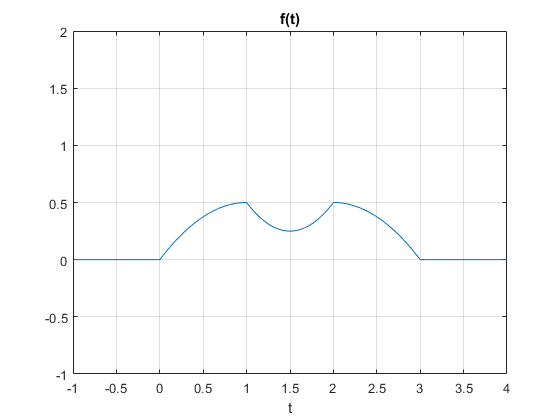

h = @(t) (-(t.^2)/2 + t).*((0 < t)&(t<=1)) + (t.^2-3*t+5/2).*((1 < t)&(t<=2))+ (-(t.^2)/2 + 2*t - 3/2).*((2 < t)&(t <= 3));
hV = (-1:0.01: 4);
plot(hV, h(hV));
axis([-1 4 -1 2]);
title('f(t)');
xlabel('t');
grid on;

Comparando la señal de la numérica generada con su resultado analítico, podemos observar que concuerda correctamente, esto se puede visualizar bien debido a que son intervalos muy pequeños los que se estan uniendo con rectas.

Esta sería el ejemplo gráfico de como se generaría la convolución.

z =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


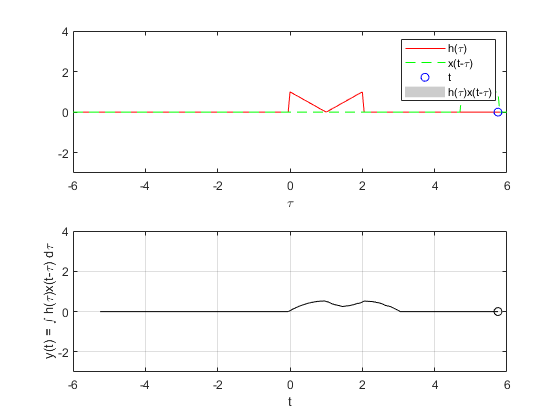

convconm(f,x, 'Problema1.gif');

### **Problema 3**

clear all; clc; close all;

Las Señales del PR04, 3er problema son:

$\[ y(t) = \begin{cases} 
      t & 0\lt t \lt 1 \\
      1 & 1\lt x\lt 2 \\
      0 & otro \ caso 
   \end{cases}
\]$ y $\[ x(t) = \begin{cases} 
      1  & 1\lt t \lt 3 \\
      0 & otro \ caso 
   \end{cases}
\]$

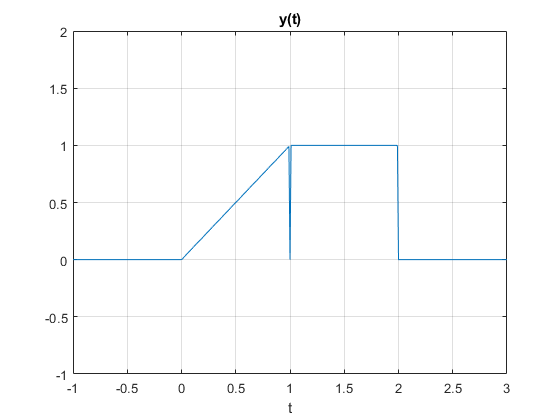

y = @(t) (t).*((t > 0) & (t<1)) + (1).*((1 < t)&(t < 2));
yV = (-1: 0.01: 4);
plot(yV, y(yV));
axis([-1 3 -1 2]);
title('y(t)');
xlabel('t');
grid on;

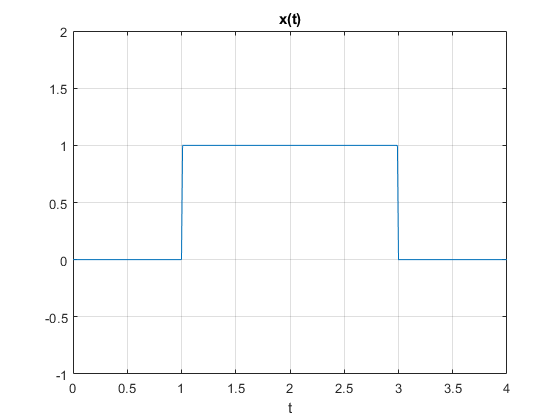

x = @(t) (1).*((t > 1) & (t<3));
xV = (-1: 0.01: 4);
plot(xV, x(xV));
axis([0 4 -1 2]);
title('x(t)');
xlabel('t');
grid on;

Para aplicar la convolución, usaríamos la definición y nuestra señal inversa movible  va a ser x(t):


$$g(x) = y(t)*x(t)= \int_{-\infty}^{\infty}y(\tau)x(t-\tau)\, d\tau$$


La convolución resultante sería:


$$\[ h(t) = 
\begin{cases}
\frac{1}{2}(-1+t)^2 & 1 \lt t \leq 2 \\
\frac{1}{2}(-3+2t) &2 \lt t \leq 3 \\ 
\frac{1}{2}(-6+6t-t^2) & 3 \lt t < 4 \\
5-t & 4 \leq t < 5 \\
0 & otro\ caso
\end{cases}
\]$$


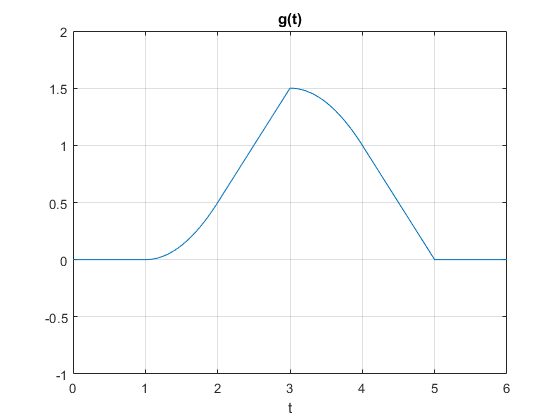

g = @(t) (1/2*(-1+t).^2).*((1 < t)&(t<=2)) + (1/2*(-3+2*t)).*((2 < t)&(t<=3))+ (1/2*(-6+6*t-t.^2)).*((3 < t)&(t < 4))+(5-t).*((4 <= t)&(t < 5));
gV = (-1:0.01: 6);
plot(gV, g(gV));
axis([0 6 -1 2]);
title('g(t)');
xlabel('t');
grid on;

Al comparar la señal generada de la numérica con su resultado analítico, podemos observar que concuerda correctamente debido a que son intervalos muy pequeños los que se estan uniendo con rectas.

Este es el ejemplo gráfico de cómo se generaría la convolución.

z =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


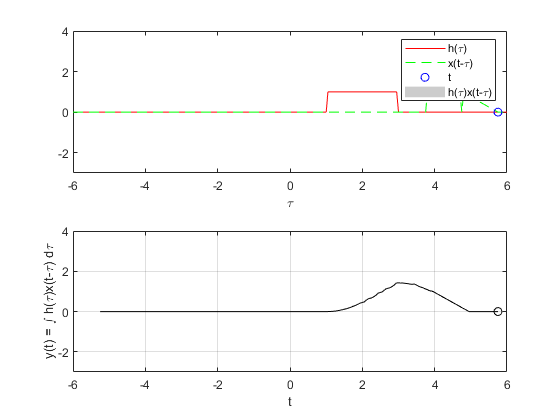

convconm(y,x, 'Problema3.gif');


$$\[ h(t) = 
\begin{cases}
\frac{1}{2}(-1+t)^2 & 1 \lt t \leq 2 \\
\frac{1}{2}(31+2t) &2 \lt t \leq 3 \\ 
\frac{1}{2}(-t+6t-t^2) & 3 \lt t \lt 4 \\
5 - t & 4 \leq t \lt 5 \\
0 & otro\ caso
\end{cases}
\]$$


## Correlación: PR06

### Inciso  e)

clear all; clc; close all;

En el inciso e) se realiza la autocorrelación de la siguiente señal: $x_1(t)=u(t)-2u(t-3)+u(t-4)$ también 


$$\[ x_1(t) = 
\begin{cases}
1 \ &0<t<3 \\
-1 \ & 3<t<4\\
0 \ &otro\ caso
\end{cases}
\]$$


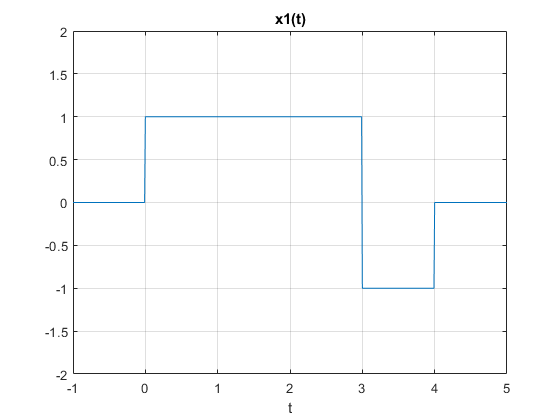

%Definiendo x1(t)
x1 = @(t) (1).*((t >= 0) & (t<3)) + (-1).*((t>=3)&(t < 4));
x1V = (-1: 0.01: 5);
plot(x1V, x1(x1V));
axis([-1 5 -2 2]);
title('x1(t)');
xlabel('t');
grid on;

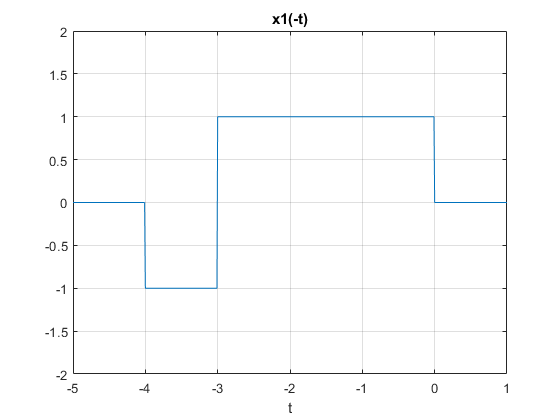


%Definiendo x1(-t)
x1n = @(t) (-1).*((t >= -4) & (t<-3)) + (1).*((t >= -3)&(t < 0));
x1V = (-5: 0.01: 1);
plot(x1V, x1n(x1V));
axis([-5 1 -2 2]);
title('x1(-t)');
xlabel('t');
grid on;

Para aplicar la convolución, usaríamos la definición y nuestra señal inversa movible  va a ser x(t):


$$g(x) = y(t)*x(t)= \int_{-\infty}^{\infty}y(\tau)x(t-\tau)\, d\tau$$


El resultado analítico de la convolución es:


$$\[ g(t) = 
\begin{cases}
-t-4 & -4  \lt   t  \lt -3 \\
t+2 & -3  \lt   t  \lt -1 \\
3t+4 & -1  \lt   t  \lt 0 \\
-3t+4 & 0  \lt   t  \lt 1 \\
-t+2 &  1  \lt   t  \lt 3 \\
t-4 & 3 \lt   t  \lt 4 \\
0 & otro\ caso
\end{cases}
\]$$


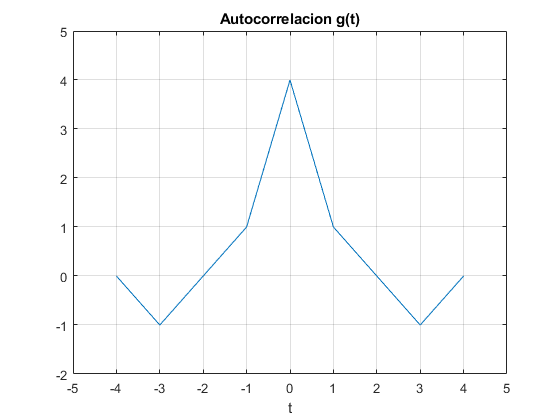

g = @(t) (-t-4).*((t > -4) & (t<-3)) + (t+2).*((t >= -3) & (t<-1)) ...
    + (3*t+4).*((t >= -1) & (t<0)) + (-3*t+4).*((t >= 0) & (t<1)) ...
    + (-t+2).*((t >= 1) & (t<3)) + (t-4).*((t >= 3) & (t<4));

gV = (-4:0.01: 4);
plot(gV, g(gV));
axis([-5 5 -2 5]);
title('Autocorrelacion g(t)');
xlabel('t');
grid on;

Para generar el gif:

z =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


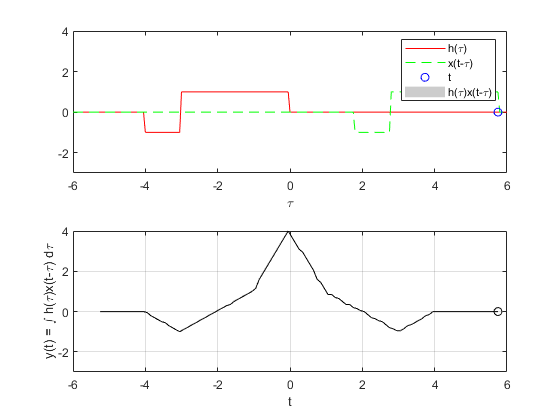

convconm(x1,x1n, 'PR06_e.gif');

### Inciso f)

clear all; clc; close all;

Las señales son

$x_0 \left(t\right)=u\left(t\right)-2u\left(t-2\right)+u\left(t-4\right)$ y $x_1(t)=u(t)-2u(t-3)+u(t-4)$

O también :


$$x_0(t)=\begin{cases}
1 \ & 0<t<2 \\
-1 \ & 2<t<4\\
0  \ & otro \ caso
\end{cases}$$



$$\[ x_1(t) = 
\begin{cases}
1 \ &0<t<3 \\
-1 \ & 3<t<4\\
0 \ &otro\ caso
\end{cases}
\]$$


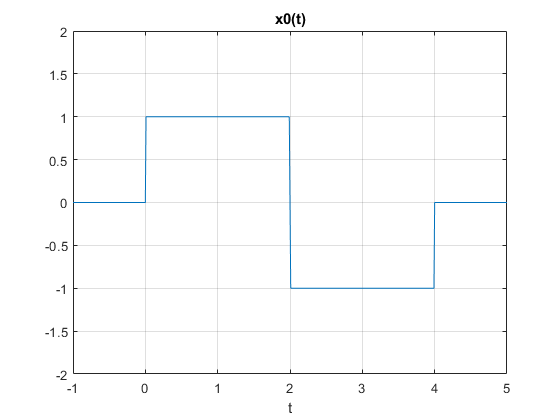

%Definiendo x0
x0 = @(t) (1).*((t > 0) & (t<2)) + (-1).*((2 < t)&(t < 4));
x0V = (-1: 0.01: 5);
plot(x0V, x0(x0V));
axis([-1 5 -2 2]);
title('x0(t)');
xlabel('t');
grid on;

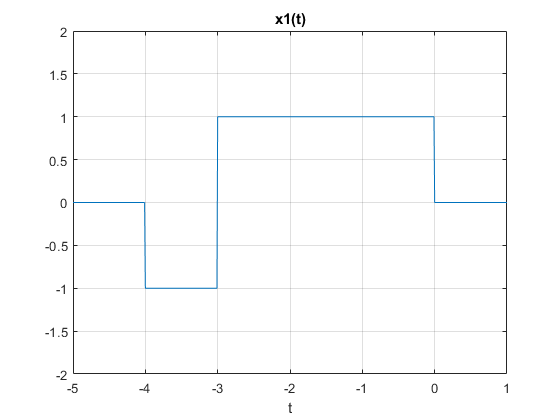


%Definiendo x1
x1 = @(t) (-1).*((t >= -4) & (t<-3)) + (1).*((t >= -3)&(t < 0));
x1V = (-5: 0.01: 1);
plot(x1V, x1(x1V));
axis([-5 1 -2 2]);
title('x1(t)');
xlabel('t');
grid on;

Para aplicar la convolución, usaríamos la definición y nuestra señal inversa movible  va a ser x(t):


$$g(x) = y(t)*x(t)= \int_{-\infty}^{\infty}y(\tau)x(t-\tau)\, d\tau$$


El resultado analítico de la convolución es:


$$\[ g(t) = 
\begin{cases}
-t-4 & -4  \lt   t  \lt -3 \\
t+2 & -3  \lt   t  \lt -2 \\
3t+6 & -2  \lt   t  \lt -1 \\
2-t & -1  \lt   t  \lt 0 \\
2-3t &  0  \lt   t  \lt 1 \\
-t & 1 \lt   t  \lt 2 \\
t-4 & 2  \lt   t  \lt 4 \\
0 & otro\ caso
\end{cases}
\]$$


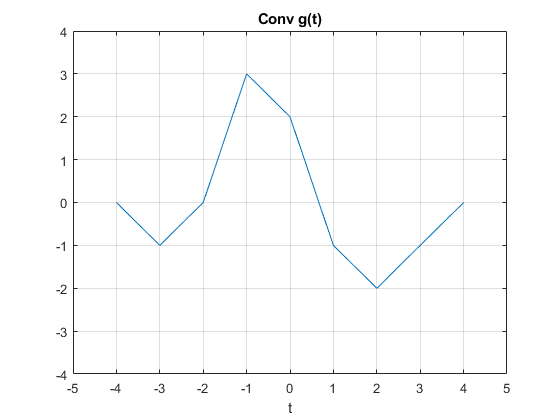

g = @(t) (-t-4).*((t > -4) & (t<-3)) + (t+2).*((t >= -3) & (t<-2)) ...
    + (3*t+6).*((t >= -2) & (t<-1)) + (2-t).*((t >= -1) & (t<0)) ...
    + (2-3*t).*((t >= 0) & (t<1)) + (-t).*((t >= 1) & (t<2)) ...
    + (t-4).*((t >= 2) & (t<4));
    
gV = (-4:0.1: 4);
plot(gV, g(gV));
axis([-5 5 -4 4]);
title('Conv g(t)');
xlabel('t');
grid on;

Para generar el gif:

z =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


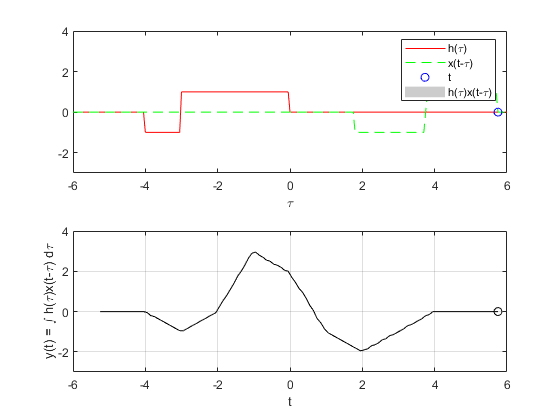

convconm(x0,x1, 'PR06_f.gif');

function convconm(x,h, filename)
  z = figure (1) % Se crea una figura para hacer las gráficas
  dtau = 0.05; % Base de los rectangulos para realizar la integral 
  tau = -6:dtau:6; % Intervalo de visualización del resultado
  ti = 0; % Indice para el vector de resultados
  tvec = -5.25:.1:5.75; % traslaciones de t, cuantas integrales se calulan  
  y = NaN*zeros(1, length (tvec)); % Resultados de acuerdo a cuantos t
  for t = tvec, % Cantidad de traslaciones
      ti = ti+1; % Indice para guardar el resultado (indice del tiempo)
      xh = x(t-tau).*h(tau); % resultado de la multiplicación 
      lxh = length(xh); % longitud del resultado
      y(ti) = sum(xh.*dtau); % Base por altura, aproximación de la integral
      subplot (2,1,1), % gráfica de 2 x 1 (primera)
      plot(tau, h(tau), 'r-', tau, x(t-tau), 'g--', t, 0, 'ob'); %graficas 
      axis ([tau(1) tau(end) -3.0 4.0]); % límites de los ejes
      patch([tau(1:end-1); tau(1:end-1); tau(2:end); tau(2:end)],...
      [zeros(1,lxh-1);xh(1:end-1);xh(2:end);zeros(1,lxh-1)],...
      [.8 .8 .8], 'edgecolor', 'none');
      xlabel('\tau'); % Texto del eje X
      legend('h(\tau)', 'x(t-\tau)','t','h(\tau)x(t-\tau)')% Caja de Texto  
      subplot (2, 1, 2)  % gráfica de 2 x 1 (segunda)
      plot (tvec, y, 'k', tvec (ti), y(ti), 'ok');
      xlabel ('t'); 
      ylabel ('y(t) = \int h(\tau)x(t-\tau) d\tau');
      axis ([tau(1) tau(end) -3.0 4.0]); % límites del eje
      grid; % malla
      drawnow; % efecto de movimiento continuo
      frame = getframe(z);
  
      im = frame2im(frame);
      [imind, cm] = rgb2ind(im, 256);
      
      if t == -5.25
          imwrite(imind, cm, filename, 'gif', 'Loopcount', inf);
      else
          imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append');
      end
  
  end
end
